# Energy Storage 2

Yen-Chun Chen

934559635

clc
close all   % close figure windows
clear
format compact

## Run initialization and simulation

hw_energystorage2_init

Good job!  The init file ran succesfully, hopefully the simulation does too.


simresults = sim("hw_energystorage2_incomplete");  % Run simulation
log = simresults.logsout;
x = log.getElement("w").Values.Time;

## 1) & 3)

- Create a signal for the combined wind turbine plus energy storage system: p_sys = p_wt + p_es.

- Create signal p_es_ref, which will be p_sys_ref - p_wt.  This is the difference between the desired system output and what the wind turbine is providing, which therefore must be the power provided by the energy storage.

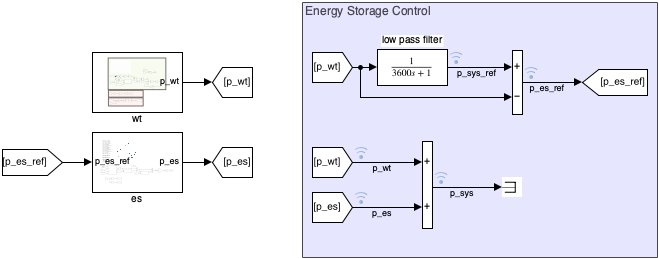

% print('-shw_energystorage2_incomplete','-dpng', 'hw_energystorage2_incomplete')

## 2)

Create desired system output signal p_sys_ref which will be the actual wind turbine power after low pass filtering.  Use a single pole low pass filter with a time constant of 3600 seconds (one hour).

Transfer funtion of single pole low-pass filter: $$$ H(s) = \frac{1}{3600s+1} $$
$

## 4)

Create a script that runs the simulation, and plots

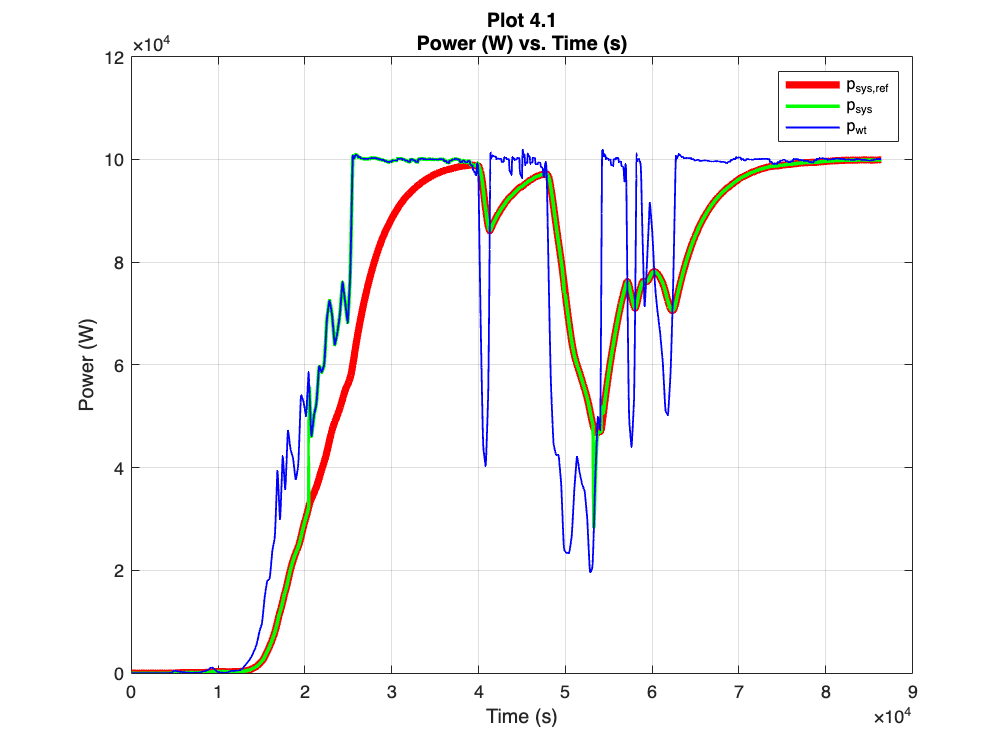

% 1) p_sys_ref, p_sys, p_wt;
figure
y_p_sys_ref = log.getElement("p_sys_ref").Values.Data;
y_p_sys = log.getElement("p_sys").Values.Data;
y_p_wt = log.getElement("p_wt").Values.Data;
p1 = plot(x, y_p_sys_ref, "-r", x, y_p_sys, "-g", x, y_p_wt, "-b");
p1(1).LineWidth = 4;
p1(2).LineWidth = 2;
p1(3).LineWidth = 1;
ylabel("Power (W)");
legend({"p_{sys,ref}","p_{sys}", "p_{wt}"});
xlabel("Time (s)");
title({'Plot 4.1','Power (W) vs. Time (s)'});
grid on

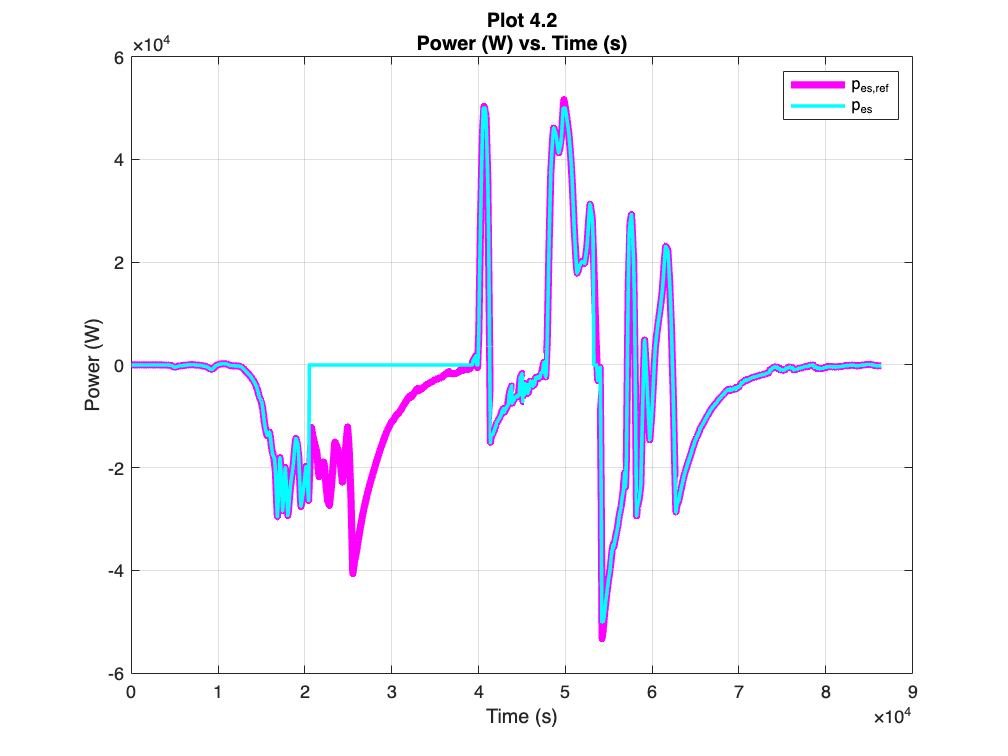

% 2) p_es_ref, p_es;
figure
y_p_es_ref = log.getElement("p_es_ref").Values.Data;
yp_es = log.getElement("p_es").Values.Data;
p2 = plot(x, y_p_es_ref, "-m", x, yp_es, "-c");
p2(1).LineWidth = 4;
p2(2).LineWidth = 2;
ylabel("Power (W)");
legend({"p_{es,ref}","p_{es}"});
xlabel("Time (s)");
title({'Plot 4.2','Power (W) vs. Time (s)'});
grid on

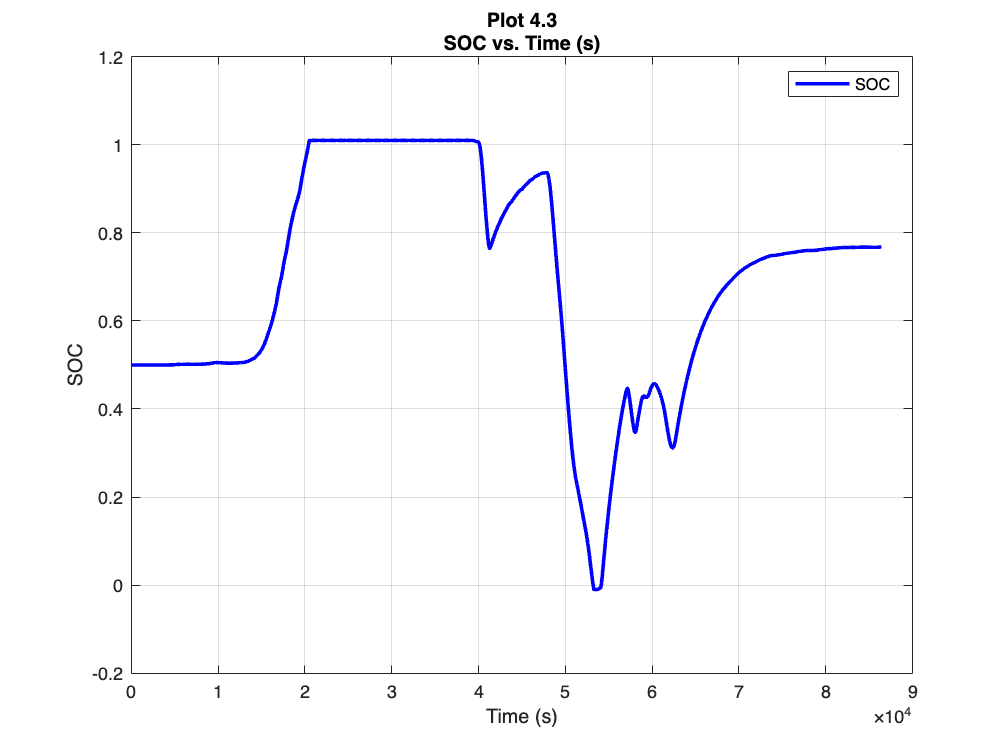

% 3) SOC.
figure
p3 = plot(x, log.getElement("SOC").Values.Data, "-b", 'LineWidth', 2);
ylabel("SOC");
legend({"SOC"});
xlabel("Time (s)");
title({'Plot 4.3','SOC vs. Time (s)'});
grid on

Present the plots in a clear manner.

## 5)

Explore how small you can make the energy storage (in terms of energy capacity rating in kWh) and still get good performance.  Explain.(You are looking for the smallest es.E_rated_kWh that allows p_sys to track p_sys_ref well.  If you make the energy storage capacity small enough, you will see it start to fail.  Why?)

To find the smallest es.E_rated_kWh that allows p_sys to track p_sys_ref well, I have tried to set es.E_rated_kWh to 180 kWh, 150 kWh, 100 kWh, 80 kWh, 70 kWh, 60 kWh, and 50 kWh. The settings of es.E_rated_kWh above 60 kWh can allow p_sys to track p_sys_ref very well. However, However, when the setting value is 50 kWh, a drop of p_sys at around the 14th hour shows that it cannot follow up the p_sys_ref. So I dived deeper to get the exact value of the smallest E_rated_kWh to units digit.

The drop still exists when E_rated_kWh is 58 kWh (As Plot 4.4 shows below), while it disappears when It is 59 kWh. This implies when the capacity when the energy storage capacity is too small, the system loses its ability to smooth out variations in wind power, and we should increase more energy storage components.

Therefore, the smallest E_rated_kWh I found is **59 kWh**, which still gets good performance.

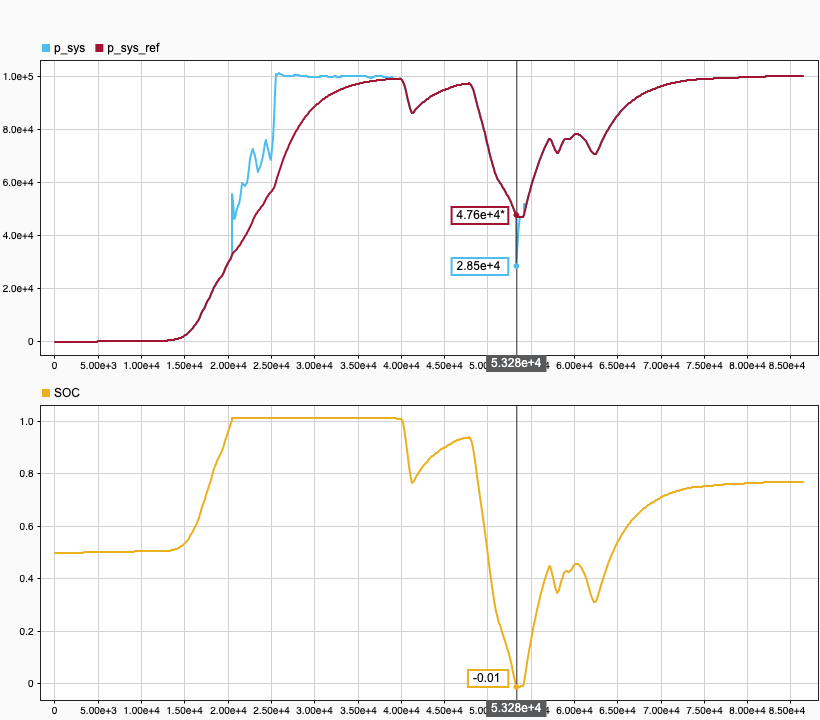

*Plot 4.4 When es.E_rated_kWh is 58 kWh, p_sys cannot follow up p_sys_ref*